clear;close all;clc;

testCase = verticalScatPlot_test;
res = testCase.run;disp(res);

Running verticalScatPlot_test
Type "dbcont" to continue:
Type "dbcont" to continue:
Type "dbcont" to continue:
.Type "dbcont" to continue:
.Type "dbcont" to continue:
Type "dbcont" to continue:
.
Done verticalScatPlot_test
__________

  1×3 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   3 Passed, 0 Failed, 0 Incomplete.
   3.7894 seconds testing time.



## testcase1

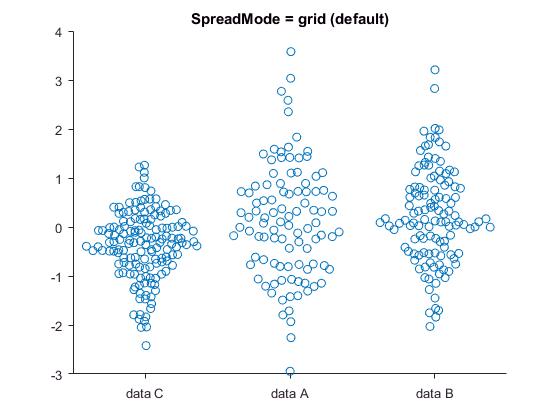

msg = @() disp('Type "dbcont" to continue:');


import matlab.unittest.constraints.IsEqualTo
import matlab.unittest.constraints.RelativeTolerance;
import matlab.unittest.TestSuite;

close all;

rng('default');
A = randn(100,1);
B = randn(120,1)+0.3;
C = randn(150,1)*0.7-0.3;

width = 0.8;

binsize = 20;


G = [repmat({'data C'}, size(C)); repmat({'data A'}, size(A)); repmat({'data B'}, size(B))];
X = [C; A; B];

verticalScatPlot(X, G); %ok
title('SpreadMode = grid (default)');

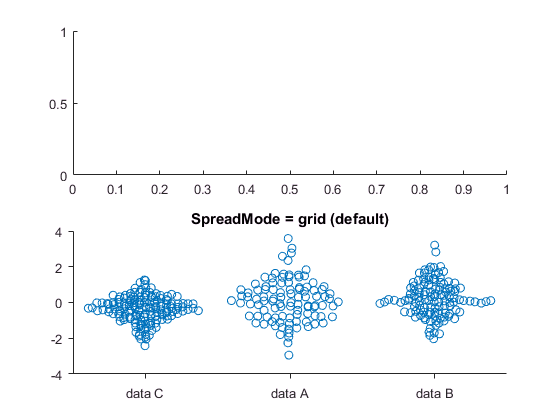

testCase.verifyEqual(get(gca, 'XTickLabel'), ...
    {'data C';'data A';'data B'});

% plot to the specified axes
figure
axh(1) = subplot(2,1,1);
axh(2) = subplot(2,1,2);
verticalScatPlot(axh(2), X, G); %ok
title('SpreadMode = grid (default)');

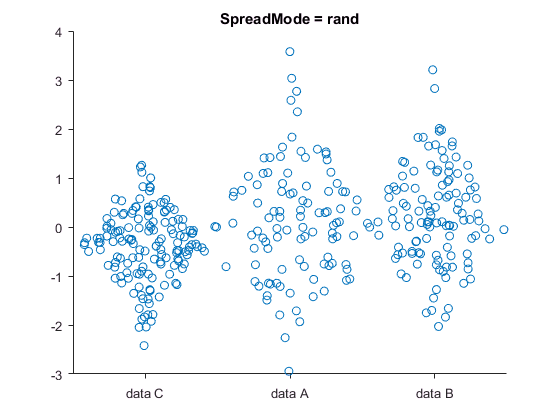

testCase.verifyEqual(get(gca, 'XTickLabel'), ...
    {'data C';'data A';'data B'});


verticalScatPlot(X, G, 'SpreadMode', 'rand');
title('SpreadMode = rand');

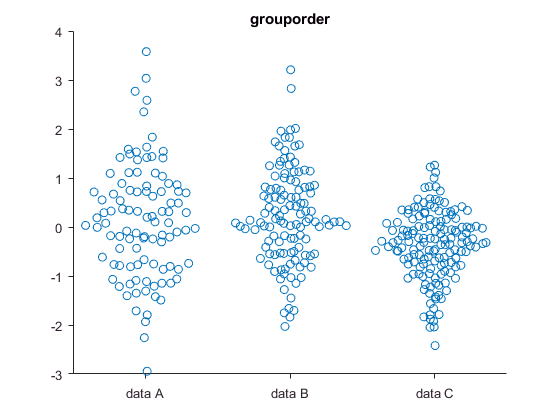

testCase.verifyEqual(get(gca, 'XTickLabel'), ...
    {'data C';'data A';'data B'});

verticalScatPlot(X, G, 'grouporder', {'data A','data B','data C'});
title('grouporder');

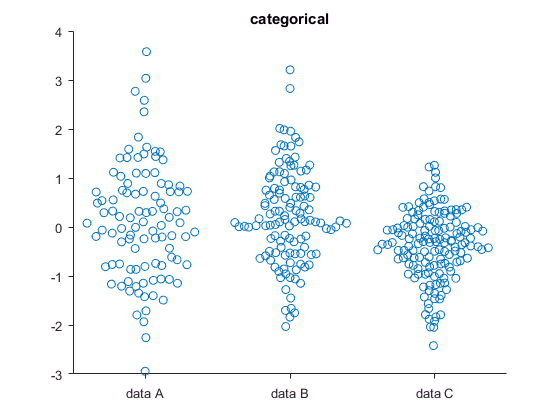

testCase.verifyEqual(get(gca, 'XTickLabel'), ...
    {'data A';'data B';'data C'});

% support categorical
g = categorical(G);
g = reordercats(g, {'data A','data B','data C'});
verticalScatPlot(X, g);
title('categorical');

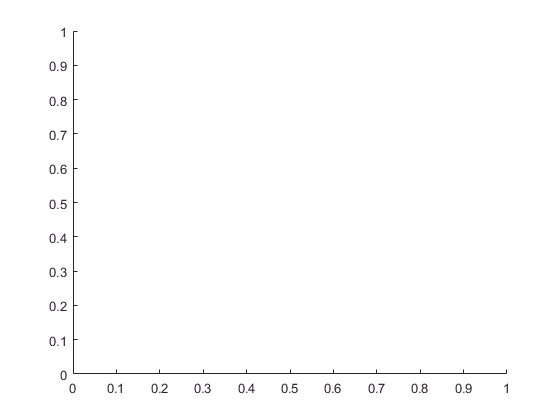

testCase.verifyEqual(get(gca, 'XTickLabel'), ...
    {'data A';'data B';'data C'});

% invalid grouporder value
testCase.verifyError(@() verticalScatPlot(X, G, 'grouporder', {'data A','data A','data B'}), ...
    'K:verticalScatPlot:grouporder:invalid');

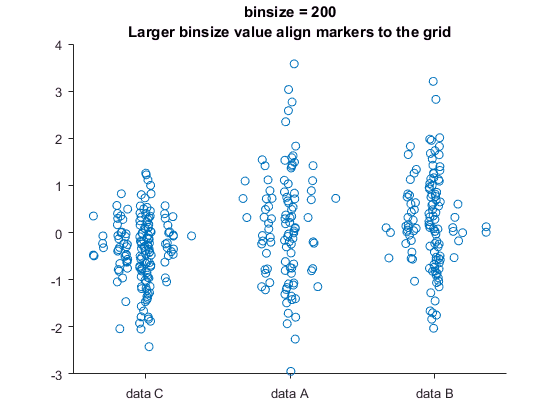



verticalScatPlot(X, G, 'binsize', 200);
title({'binsize = 200';'Larger binsize value align markers to the grid'})

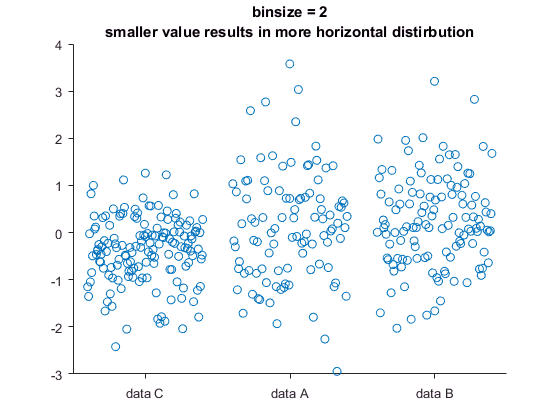


verticalScatPlot(X, G, 'binsize', 2);
title({'binsize = 2';'smaller value results in more horizontal distirbution'})

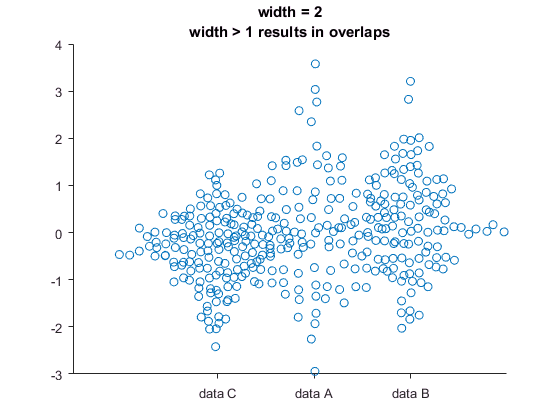


verticalScatPlot(X, G, 'width', 2);
title({'width = 2';'width > 1 results in overlaps'})

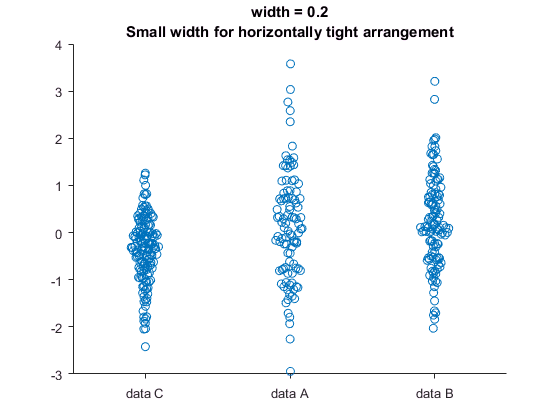


verticalScatPlot(X, G, 'width', 0.2);
title({'width = 0.2';'Small width for horizontally tight arrangement'})

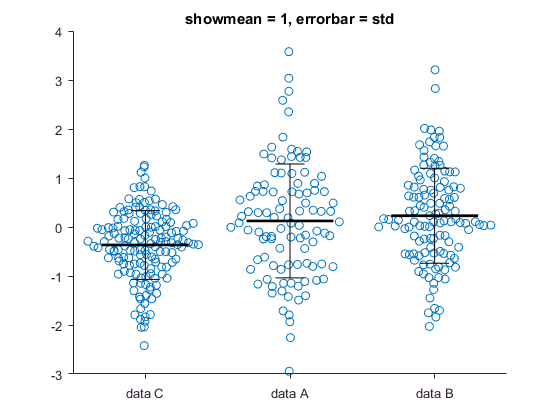




verticalScatPlot(X, G, 'showmean', 1, 'errorbar', 'std'); %ok
title('showmean = 1, errorbar = std')

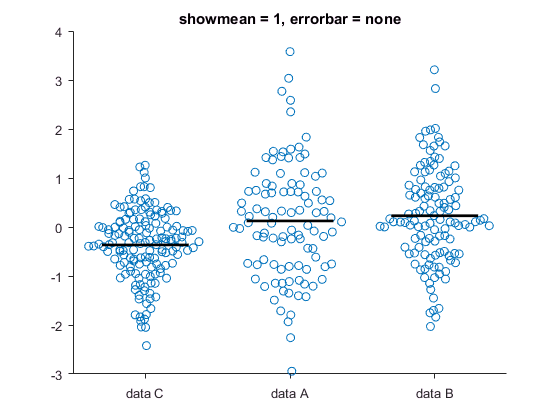


verticalScatPlot(X, G, 'showmean', 1, 'errorbar', 'NONE'); %ok
title('showmean = 1, errorbar = none')

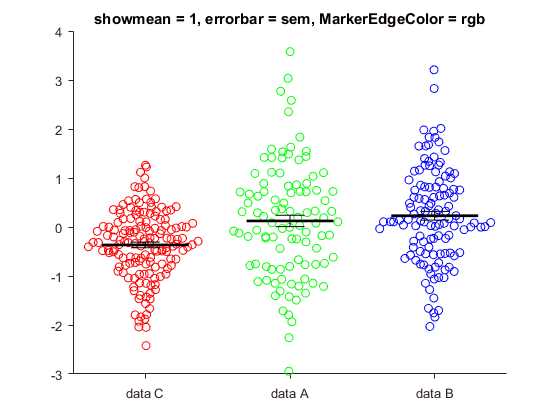


verticalScatPlot(X, G, 'showmean', 1, 'errorbar', 'sem', 'MarkerEdgeColor', 'rgb'); %ok
title('showmean = 1, errorbar = sem, MarkerEdgeColor = rgb')

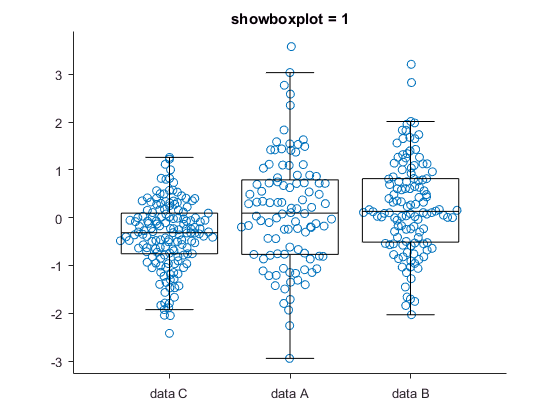




verticalScatPlot(X, G, 'SHOWBOXPLOT', true); %ok
title('showboxplot = 1')

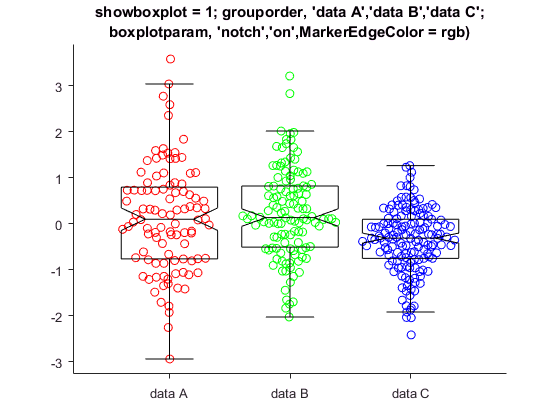



verticalScatPlot(X, G, 'SHOWBOXPLOT', true, ...
    'grouporder', {'data A','data B','data C'},...
    'boxplotparam', {'notch','on'},'MarkerEdgeColor', 'rgb'); %ok
title({'showboxplot = 1; grouporder, {''data A'',''data B'',''data C''};';...
    'boxplotparam, {''notch'',''on''},MarkerEdgeColor = rgb)'})

## colors

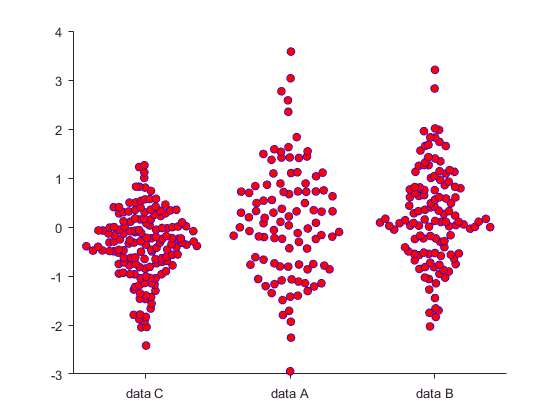

import matlab.unittest.constraints.IsEqualTo
import matlab.unittest.constraints.RelativeTolerance;
import matlab.unittest.TestSuite;

close all;

rng('default');
A = randn(100,1);
B = randn(120,1)+0.3;
C = randn(150,1)*0.7-0.3;

G = [repmat({'data C'}, size(C)); repmat({'data A'}, size(A)); repmat({'data B'}, size(B))];
X = [C; A; B];

verticalScatPlot(X, G,  'markeredgecolor', 'b', 'markerfacecolor', 'r'); %ok

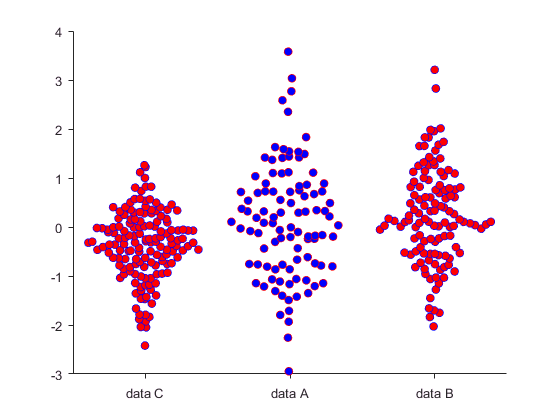


verticalScatPlot(X, G,  'markeredgecolor', 'br', 'markerfacecolor', 'rb'); %ok

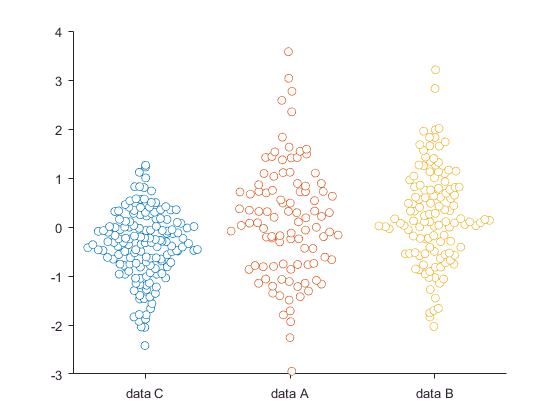


verticalScatPlot(X, G,  'markeredgecolor', 'auto', 'markerfacecolor', 'auto'); %ok

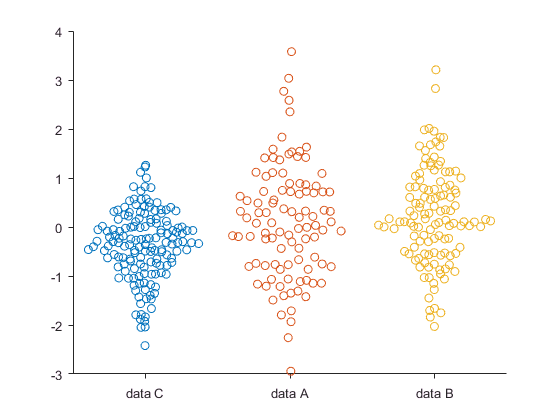


verticalScatPlot(X, G,  'markeredgecolor', 'auto', 'markerfacecolor', 'none'); %ok

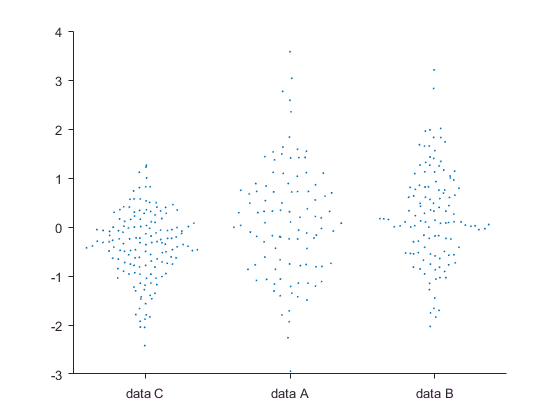


verticalScatPlot(X, G,  'markersize', 1);

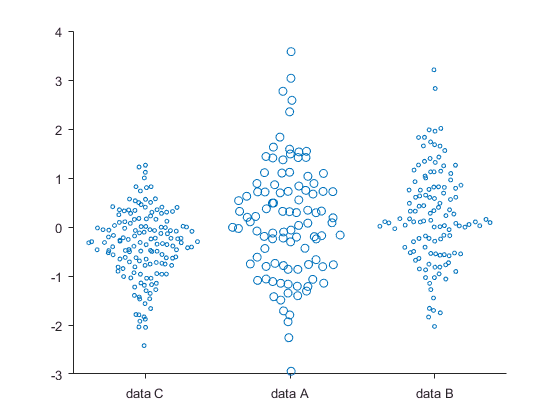


verticalScatPlot(X, G,  'markersize', [3, 6]); %ok

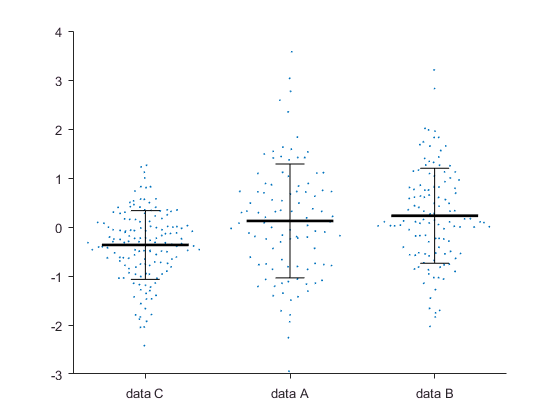


verticalScatPlot(X, G,  'markersize', 1,  'showmean', true); %ok

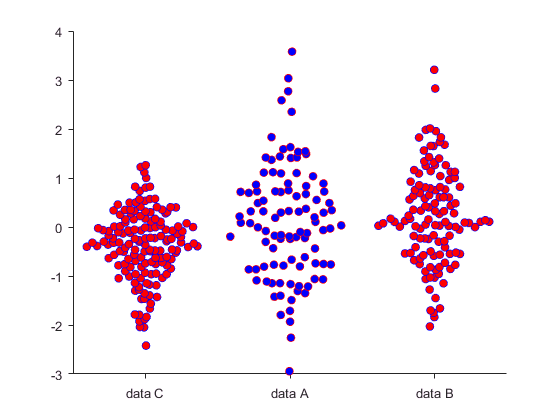


verticalScatPlot(X, G,  'markeredgecolor', 'BR', 'markerfacecolor', 'RB'); %ok

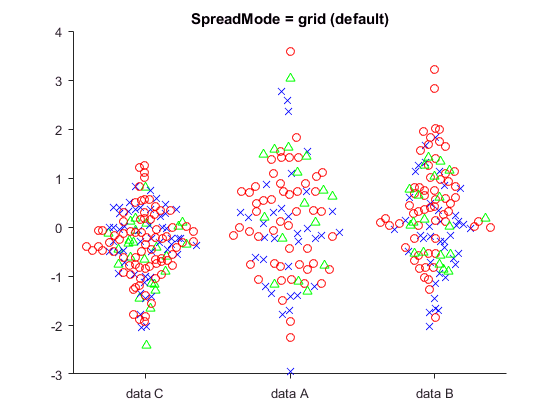

import matlab.unittest.constraints.IsEqualTo
import matlab.unittest.constraints.RelativeTolerance;
import matlab.unittest.TestSuite;

close all;

rng('default');
A = randn(100,1);
B = randn(120,1)+0.3;
C = randn(150,1)*0.7-0.3;


G = [repmat({'data C'}, size(C)); repmat({'data A'}, size(A)); repmat({'data B'}, size(B))];
X = [C; A; B];

str = {'red'; 'red'; 'red'; 'blue';'blue'; 'green'};
GG = [repmat(str, floor(length(X)/6), 1);...
    str(1:rem(length(X), 6))];
GGparams(1).label = 'red'; GGparams(1).marker = 'o'; GGparams(1).markeredgecolor = 'r';
GGparams(2).label = 'blue'; GGparams(2).marker = 'x'; GGparams(2).markeredgecolor = 'b';
GGparams(3).label = 'green'; GGparams(3).marker = '^'; GGparams(3).markeredgecolor = 'g';

forGGcopy = GGparams;

%%

verticalScatPlot(X, G, 'GG', GG, 'GGparams', GGparams); %ok
title('SpreadMode = grid (default)');

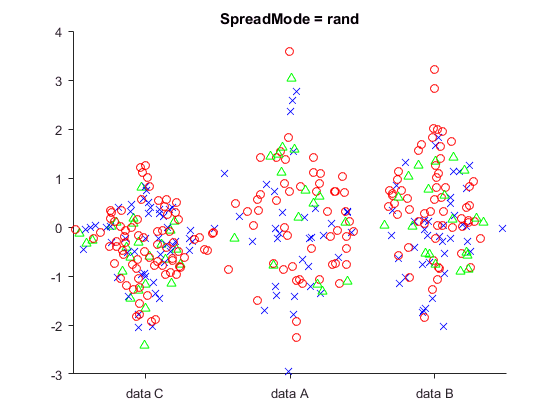

testCase.verifyEqual(get(gca, 'XTickLabel'), ...
    {'data C';'data A';'data B'});

verticalScatPlot(X, G, 'SpreadMode', 'rand', 'GG', GG, 'GGparams', GGparams); %ok
title('SpreadMode = rand');

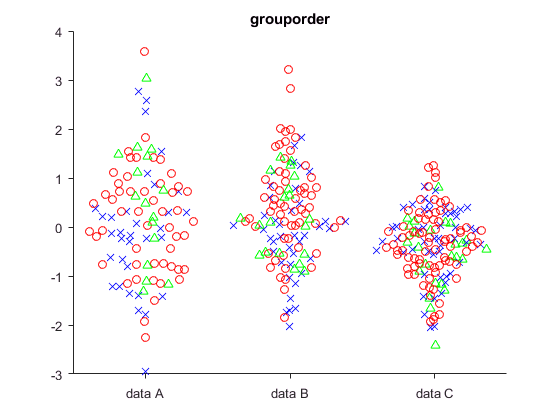

testCase.verifyEqual(get(gca, 'XTickLabel'), ...
    {'data C';'data A';'data B'});

verticalScatPlot(X, G, 'grouporder',...
    {'data A','data B','data C'}, 'GG', GG, 'GGparams', GGparams); %ok
title('grouporder');

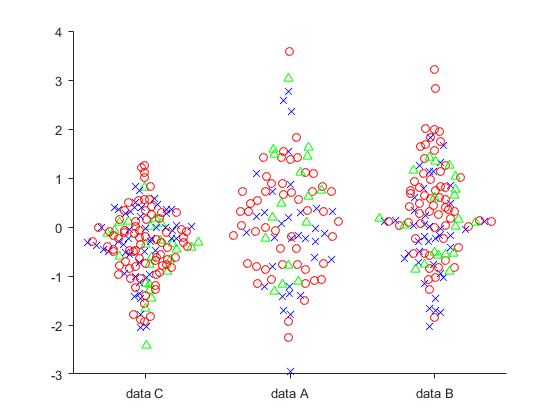

testCase.verifyEqual(get(gca, 'XTickLabel'), ...
    {'data A';'data B';'data C'});

testCase.verifyWarning(@() verticalScatPlot(X, G, 'GG', GG, ...
    'GGparams', GGparams, 'markersize', 10), ...
    'K:verticalScatPlot:local_parse:markersize:overridden');

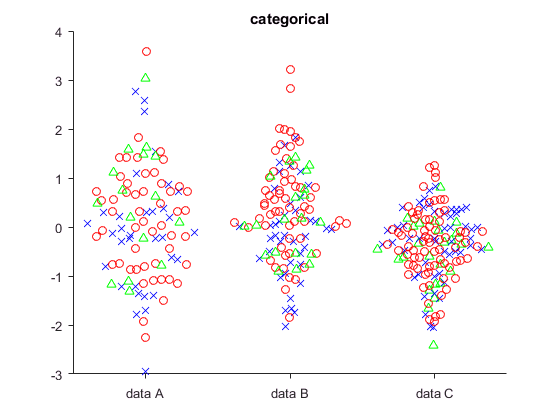


% support categorical
g = categorical(G);
g = reordercats(g, {'data A','data B','data C'});
verticalScatPlot(X, g, 'GG', GG, 'GGparams', GGparams); %ok
title('categorical');

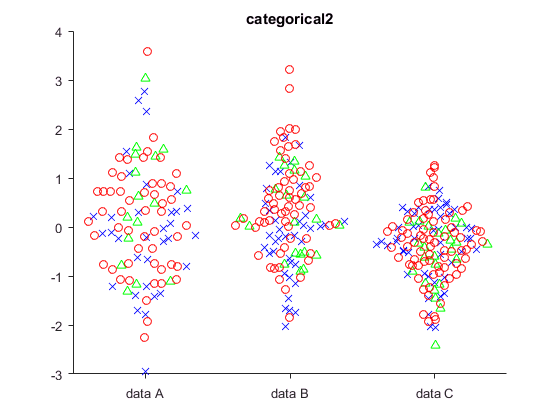

testCase.verifyEqual(get(gca, 'XTickLabel'), ...
    {'data A';'data B';'data C'});

gg = categorical(GG);
verticalScatPlot(X, g, 'GG', gg, 'GGparams', GGparams); %ok
title('categorical2');

testCase.verifyEqual(get(gca, 'XTickLabel'), ...
    {'data A';'data B';'data C'});



%%
testCase.verifyError(@() verticalScatPlot(X, G, 'GG', GG), ...
    'K:verticalScatPlot:local_parse:GGparams:invalid:length'); %ok

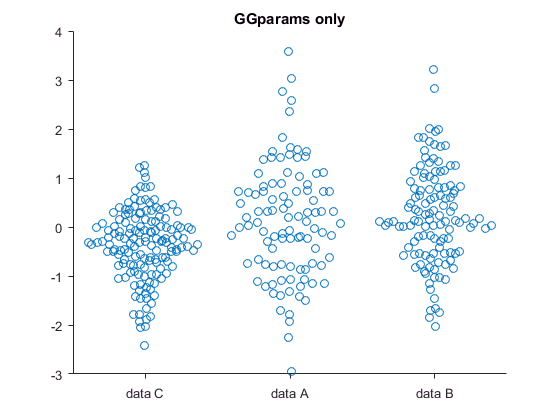


verticalScatPlot(X, G, 'GGparams', GGparams); %ok
title('GGparams only');

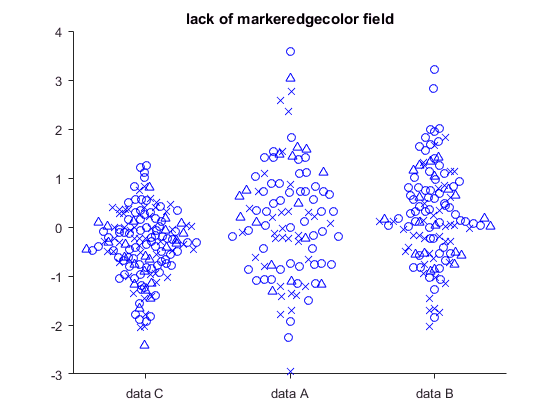

testCase.verifyEqual(get(gca, 'XTickLabel'), ...
    {'data C';'data A';'data B'});

GGparams = rmfield(GGparams, 'markeredgecolor');
verticalScatPlot(X, G, 'GG', GG, 'GGparams', GGparams); %lack of color field
title('lack of markeredgecolor field');

testCase.verifyEqual(get(gca, 'XTickLabel'), ...
    {'data C';'data A';'data B'});


